clear all;
close all;
clc;

% ------ PARTE 1 ------
%Declaração da planta
A = [0 1 0; 0 0 1; 0 -2 -3];
B = [0 0 1]';
C = [2 0 0];
D = [0];
Mp = 16.3/100;
ts = 2;
s3 = -5;

%Polos do sistema e amortecimento
zeta = -log(Mp)/(sqrt(log(Mp)^2+3.14^2));
omega_n = 4 / (zeta*ts);
sigma = zeta*omega_n;
parte_real = -zeta*omega_n;
parte_imag = omega_n*sqrt(1 - zeta^2);
polos = [(parte_real + parte_imag * j) (parte_real - parte_imag * j)]
fprintf("Zeta: %.3f / Omega_n: %.3f", zeta, omega_n);

polos =   -2.0000 + 3.4620i  -2.0000 - 3.4620i


Zeta: 0.500 / Omega_n: 3.998


%Matriz de controlabilidade
M=ctrb(A,B)

M =      0     0     1
     0     1    -3
     1    -3     7


rank(M)

ans = 3


%Controlabilidade
[linhas, colunas] = size(A)

linhas = 3

colunas = 3

if linhas == rank(M)
    disp("Sistema controlável")
else
    disp("Sistema não controlável")
end

Sistema controlável



%Cálculo do vetor de ganhos K
polos_desejados = [(parte_real + parte_imag * j) (parte_real - parte_imag * j) s3]

polos_desejados =   -2.0000 + 3.4620i  -2.0000 - 3.4620i  -5.0000 + 0.0000i


K=acker(A,B,polos_desejados)

K =    79.9256   33.9851    6.0000



%Sistema controlado em MF com kr=1
Amfc=A-B*K

Amfc =          0    1.0000         0
         0         0    1.0000
  -79.9256  -35.9851   -9.0000


Bmfc=B

Bmfc =      0
     0
     1


Cmfc=C

Cmfc =      2     0     0


Dmfc=D

Dmfc = 0

sysMFc=ss(Amfc,Bmfc,Cmfc,Dmfc);

%Cálculo de CC e kr
GanhoCC=dcgain(sysMFc)

GanhoCC = 0.0250

kr=1/GanhoCC

kr = 39.9628


%Sistema em MF sem controlador
Amf=A-B*C;
Bmf=B;
Cmf=C;
Dmf=D;
sysMF=ss(Amf,Bmf,Cmf,Dmf);

%Sistema controlado em MF com kr ajustado
Amfca=A-B*K;
Bmfca=B*kr;
Cmfca=C;
Dmfca=D;
sysMFca=ss(Amfca,Bmfca,Cmfca,Dmfca);
info = stepinfo(sysMFca);
disp(['Tempo de assentamento: ', num2str(info.SettlingTime)]);

Tempo de assentamento: 1.6344


disp(['Porcentagem de sobressinal: ', num2str(info.Overshoot)]);

Porcentagem de sobressinal: 10.6027



%Resposta ao degrau em MF
figure;
subplot(2,1,1);
step(sysMF,20);
hold;

Current plot held


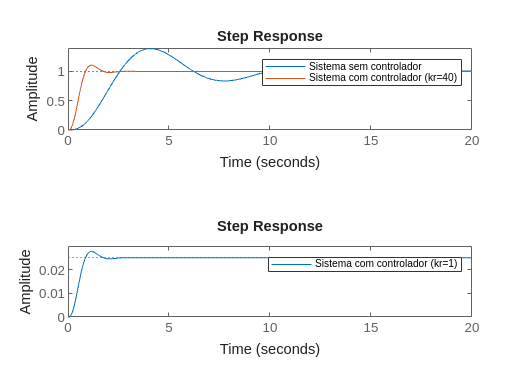

step(sysMFca,20);
legend('Sistema sem controlador','Sistema com controlador (kr=40)');
subplot(2,1,2);
step(sysMFc,20)
legend('Sistema com controlador (kr=1)');



% ------ PARTE 2 ------
disp("-------------------")

-------------------


%Declaração do polo
s3 = -20;

%Cálculo do vetor de ganhos K
polos_desejados = [(parte_real + parte_imag * j) (parte_real - parte_imag * j) s3]

polos_desejados =   -2.0000 + 3.4620i  -2.0000 - 3.4620i -20.0000 + 0.0000i


K=acker(A,B,polos_desejados)

K =   319.7023   93.9851   21.0000



%Sistema controlado em MF com kr=1
Amfc=A-B*K

Amfc =          0    1.0000         0
         0         0    1.0000
 -319.7023  -95.9851  -24.0000


Bmfc=B

Bmfc =      0
     0
     1


Cmfc=C

Cmfc =      2     0     0


Dmfc=D

Dmfc = 0

sysMFc=ss(Amfc,Bmfc,Cmfc,Dmfc);

%Cálculo de CC e kr
GanhoCC=dcgain(sysMFc)

GanhoCC = 0.0063

kr=1/GanhoCC

kr = 159.8512


%Sistema controlado em MF com kr ajustado
Amfca=A-B*K

Amfca =          0    1.0000         0
         0         0    1.0000
 -319.7023  -95.9851  -24.0000


Bmfca=B*kr

Bmfca =          0
         0
  159.8512


Cmfca=C

Cmfca =      2     0     0


Dmfca=D

Dmfca = 0

sysMFca=ss(Amfca,Bmfca,Cmfca,Dmfca);
info = stepinfo(sysMFca);
disp(['Tempo de assentamento: ', num2str(info.SettlingTime)]);

Tempo de assentamento: 2.0655


disp(['Porcentagem de sobressinal: ', num2str(info.Overshoot)]);

Porcentagem de sobressinal: 15.9187



% ------ PARTE 3 ------
disp("-------------------")

-------------------


%Declaração do polo
s3 = -50;

%Cálculo do vetor de ganhos K
polos_desejados = [(parte_real + parte_imag * j) (parte_real - parte_imag * j) s3]

polos_desejados =   -2.0000 + 3.4620i  -2.0000 - 3.4620i -50.0000 + 0.0000i


K=acker(A,B,polos_desejados)

K =   799.2559  213.9851   51.0000



%Sistema controlado em MF com kr=1
Amfc=A-B*K

Amfc =          0    1.0000         0
         0         0    1.0000
 -799.2559 -215.9851  -54.0000


Bmfc=B

Bmfc =      0
     0
     1


Cmfc=C

Cmfc =      2     0     0


Dmfc=D

Dmfc = 0

sysMFc=ss(Amfc,Bmfc,Cmfc,Dmfc);

%Cálculo de CC e kr
GanhoCC=dcgain(sysMFc)

GanhoCC = 0.0025

kr=1/GanhoCC

kr = 399.6279


%Sistema controlado em MF com kr ajustado
Amfca=A-B*K

Amfca =          0    1.0000         0
         0         0    1.0000
 -799.2559 -215.9851  -54.0000


Bmfca=B*kr

Bmfca =          0
         0
  399.6279


Cmfca=C

Cmfca =      2     0     0


Dmfca=D

Dmfca = 0

sysMFca=ss(Amfca,Bmfca,Cmfca,Dmfca);
info = stepinfo(sysMFca);
disp(['Tempo de assentamento: ', num2str(info.SettlingTime)]);

Tempo de assentamento: 2.0389


disp(['Porcentagem de sobressinal: ', num2str(info.Overshoot)]);

Porcentagem de sobressinal: 16.2234
